# Automatized code 

clear all 
close all
clc

% extraction data of interest 
fprintf('\n Code about the generation of FID signal \n\n')


 Code about the generation of FID signal 



fprintf(' Press a key to choose an rawxx folder \n\n');

 Press a key to choose an rawxx folder 



pause
baseFolder='C:\Users\chiar\Documents\tesi IBEC doc\materials'

baseFolder = 'C:\Users\chiar\Documents\tesi IBEC doc\materials'

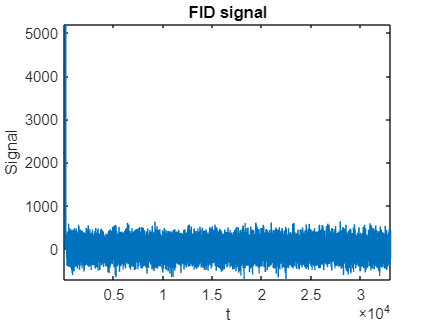

[file,path]=uigetfile(join([baseFolder,'\*.fid*']),'Load');
filename=sprintf('%s%s',path,file);
h=fopen(filename,'r');
fid_delay=fread(h,inf,'float');
fclose(h);

% baseFolder='2023_11_03_DGC_NK_8M_HepG2_Rep1';
% selpath=uigetdir(baseFolder)

figure;
plot(fid_delay)
title('FID signal')
xlabel('t')
ylabel('Signal')
axis tight;


% test 2 
idx = find(fid_delay==0); 
delay=zeros()

delay = 0

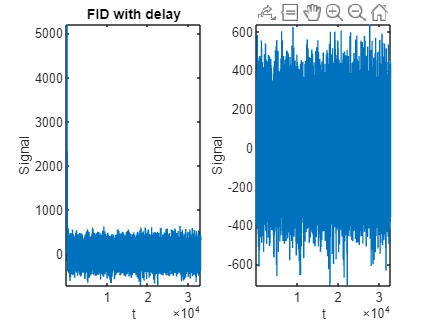

for j=1:length(idx)-1
    if idx(j+1)-idx(j) <= 3
        delay(j)=idx(j);
    end
end

fid = fid_delay(delay(end):end); % delay deleted

subplot(121)
plot(fid_delay)
axis tight; 
title ('FID with delay')
xlabel('t')
ylabel('Signal')
subplot(122)
plot(fid)
axis tight; 
title ('FIF without delay')
xlabel('t')
ylabel('Signal')

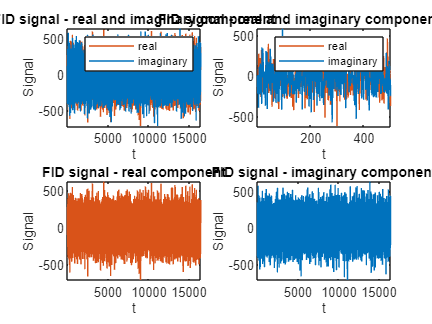


% separation real and imaginary part
n = length(fid); % number of rows 
M = repmat((1:n)',1,1); 
real_part=M(1:2:end,:); % odd matrix
real_fid = fid(real_part); 
img_part=M(2:2:end,:); % even matrix
img_fid = fid(img_part); 


figure; 
subplot(221)
plot(real_fid, 'Color',[0.8510    0.3255    0.0980])
hold on
axis tight;
plot(img_fid, 'Color',[0    0.4471    0.7412])
hold off
axis tight;
legend('real', 'imaginary')
xlabel('t')
ylabel('Signal')
title ('FID signal - real and imaginary component')

subplot(222)
plot(real_fid(1:500), 'Color',[0.8510    0.3255    0.0980])
hold on
axis tight;
plot(img_fid(1:500), 'Color',[0    0.4471    0.7412])
hold off
axis tight;
legend('real', 'imaginary')
xlabel('t')
ylabel('Signal')
title ('FID signal - real and imaginary component (zoom)')

subplot(223)
plot(real_fid, 'Color',[0.8510    0.3255    0.0980])
axis tight;
xlabel('t')
ylabel('Signal')
title ('FID signal - real component')

subplot(224)
plot(img_fid, 'Color',[0    0.4471    0.7412])
axis tight;
xlabel('t')
ylabel('Signal')
title ('FID signal - imaginary component')

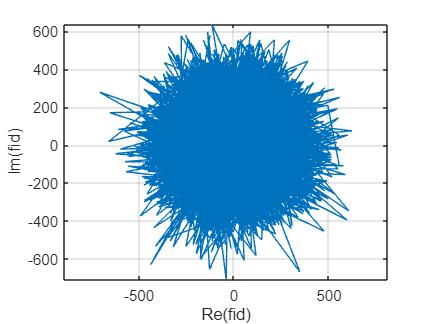


new_fid = real_fid(1:end-1)+i*(img_fid);
figure; 
plot(new_fid,"-"); 
axis equal 
grid on 
xlabel("Re(fid)")
ylabel("Im(fid)")